**Rutherford szórási kísérlet**

Rutherford szórási kísérlet jól modellezhető a Coulomb-erőt definiáló egyenletből:


$$$$\mathbf{F}=k \cdot \frac{q_1 q_2}{r^3} \cdot \mathbf{r}$$$$


ahol $$q_1$
$: alpha részecske töltése, $$q_2$$: arany atommag töltése, r az adott pillanatban az atom középpontja és az alpha részecske távolsága, k pedig a Coulomb állandó.

A szimuláció elkészítéséhez a kezdeti értékeket és a változók értékadásához szükséges adatokat a következő oldalakról kerestem ki: [https://en.wikipedia.org/wiki/Rutherford_scattering,](https://en.wikipedia.org/wiki/Rutherford_scattering,) [https://www.webelements.com/gold/crystal_structure.html,](https://www.webelements.com/gold/crystal_structure.html,) [https://en.wikipedia.org/wiki/Bohr_radius](https://en.wikipedia.org/wiki/Bohr_radius) . 

Először azt modelleztem, hogy egy darab aranyatomot lövünk 101 darab alfa részecskével vízszintes irányból, különböző magasságból. Ez azt jelenti, hogy $$x_0$$ állandó minden lövésnél: $$x_0=10^{-10} $$ m, és a részecskék pályáját 101 különböző magasságból indított részecskénél vizsgáljuk, a lépésköz állandó: $$\Delta y_0= 10^{-12}$$ m, $$y_0=-50 \cdot 10^{-12}$ m és $$y_0=50 \cdot 10^{-12}$$ m között. Kirajzoltam az arany atom Bohr sugarát, ami $$r_B=5.29177 \cdot 10^{-11}$$ m.

Az állandóknak a következőképpen adtam értékeket, illetve először a kezdeti sebességnek $$v_0=6 \cdot 10^{5} \frac{m}{s}$$-ot választottam:

clear all, close all;

k=8.987551e+9; %Coulomb allando [Nm^2/C^2]
q1=2*1.6021766e-19; %alpha (helium) [C]
q2=79*1.6021766e-19; %arany [C]
m=6.624424e-27; %[kg]
km=k/m;
v0=6e+5; %kezdeti sebesseg [m/s]

Először Euler módszerrel csináltam meg a feladatot, a következő egyenleteket felhasználva:


$$$$\mathbf{\dot{v}}=\frac{1}{m} \cdot k \cdot \frac{q_1 q_2}{r^3} \cdot \mathbf{r}$$
$$



$$$$\mathbf{\dot{r}}=\mathbf{v}$$$$


$$a_x=\frac{1}{m}k \frac{q_1q_2}{(x^2+y^2)^{\frac{3}{2}}} \cdot x$$;     $$a_y=\frac{1}{m}k \frac{q_1q_2}{(x^2+y^2)^{\frac{3}{2}}} \cdot y$$

$$v_x=v_x+a_x\cdot dt$$;               $$$v_y=v_y+a_y \cdot dt$$
$

$$$x=x+v_x \cdot dt$$
$;                 $$$y=y+v_y \cdot dt$$
$

A $$dt=10^{-19}$$ lépésköz elegendően kicsinek bizonyult. A kódot futtatva láthatjuk az alpha részecskék pályáját a kilövést követően.

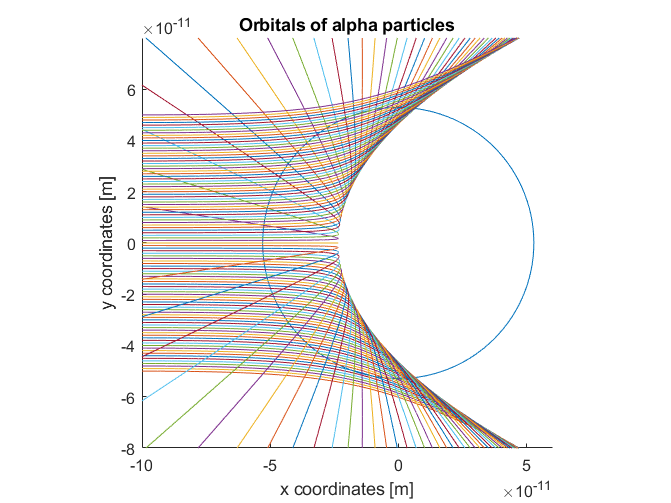

dt=1e-19;
figure(1);
rc=5.29177e-11;
th=0:pi/60:2*pi;
xunit=rc*cos(th);
yunit=rc*sin(th);
hold on;
plot(xunit, yunit)
hold on
for j=-50:50
    vx=v0;
    vy=0;
    rx=1e-10;
    ry=j*1e-12;
    x=-rx;
    y=ry;

    x_=[x];
    y_=[y];
    vx_=[vx];
    vy_=[vy];
    for i=0:10000
       
        r=sqrt(x^2+y^2);

        ax=km*q1*q2*x /r^3;
        ay=km*q1*q2*y /r^3;

        vx=vx+ax*dt;
        vy=vy+ay*dt;

        vx_=[vx_ vx];
        vy_=[vy_ vy];

        x=x+vx*dt;
        y=y+vy*dt;

        x_=[x_ x];
        y_=[y_ y];
    end
    plot(x_, y_)
    hold on;
end

 pbaspect([1 1 1])
 xlim([-10e-11, 6e-11]);
 ylim([-8e-11, 8e-11]);
 xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbitals of alpha particles');

Nagyobb kezdősebességnél ($$v_0=10^6 \frac{m}{s}$ ) láthatjuk, hogy az alfa részecskék kevésbé térülnek el:

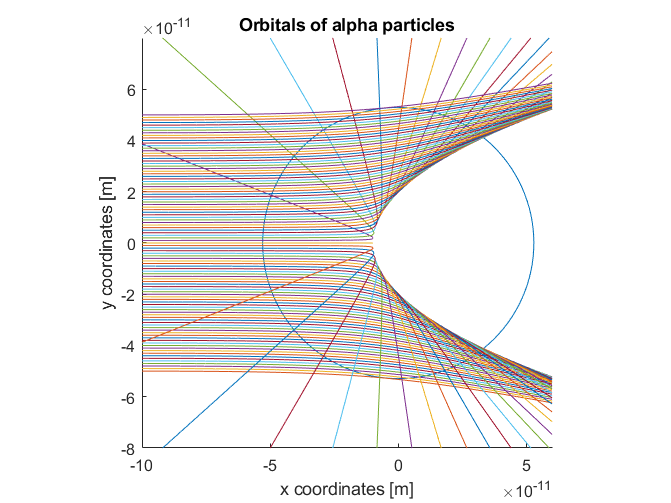

dt=1e-19;
v0=1e+6;
figure(2);
rc=5.29177e-11;
th=0:pi/60:2*pi;
xunit=rc*cos(th);
yunit=rc*sin(th);
hold on;
plot(xunit, yunit)
hold on
for j=-50:50
    vx=v0;
    vy=0;
    rx=1e-10;
    ry=j*1e-12;
    x=-rx;
    y=ry;

    x_=[x];
    y_=[y];
    vx_=[vx];
    vy_=[vy];
    for i=0:10000
       
        r=sqrt(x^2+y^2);

        ax=km*q1*q2*x /r^3;
        ay=km*q1*q2*y /r^3;

        vx=vx+ax*dt;
        vy=vy+ay*dt;

        vx_=[vx_ vx];
        vy_=[vy_ vy];

        x=x+vx*dt;
        y=y+vy*dt;

        x_=[x_ x];
        y_=[y_ y];
    end
    plot(x_, y_)
    hold on;
end

 pbaspect([1 1 1])
 xlim([-10e-11, 6e-11]);
 ylim([-8e-11, 8e-11]);
 xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbitals of alpha particles');

Ezután egy aranyfóliával modelleztem a kísérletet. Kikerestem, hogy az arany rácsszerkezetében mekkora távolságra vannak az atomok. Az átlagos távolság: $$D=4.065 \cdot 10^{-10}$$ m. 7 darab arany atommal végeztem a számítást és 301 alfa récsecskével, először Euler módszerrel. A előzőekhez képest annyíban változtak az egyenletek, hogy az összes arany atommag töltését figyelembe kell venni a Coulomb-törvényben, és az abból kiszámított mozgásegyenletbe is bele kell írni.

A kiindulópontok: $$x_0=-4 \cdot 10^{-10}$$ m, és 301 különböző magasságból indítjuk a részecskéket $$y_0=-150\cdot 10^{-11}$$m és $$y_0=+150\cdot 10^{-11}$$ m között, állandó $$\Delta y_0= 10^{-11}$$ lépésközzel.


$$$$a_x=\frac{1}{m}k q_1q_2x \cdot \bigg(\frac{1}{(x^2+y^2)^{\frac{3}{2}}} + \frac{1}{(x^2+(y-D)^2)^{\frac{3}{2}}} +
\frac{1}{(x^2+(y-2D)^2)^{\frac{3}{2}}}+\frac{1}{(x^2+(y+D)^2)^{\frac{3}{2}}} + \frac{1}{(x^2+(y+2D)^2)^{\frac{3}{2}}}\bigg)$$$$



$$$$a_y=\frac{1}{m}k q_1q_2 \cdot \bigg(\frac{y}{(x^2+y^2)^{\frac{3}{2}}} + \frac{y-D}{(x^2+(y-D)^2)^{\frac{3}{2}}} +
\frac{y-2D}{(x^2+(y-2D)^2)^{\frac{3}{2}}}+\frac{y+D}{(x^2+(y+D)^2)^{\frac{3}{2}}} + \frac{y+2D}{(x^2+(y+2D)^2)^{\frac{3}{2}}}\bigg)$$$$


$$v_x=v_x+a_x\cdot dt$$;        $$v_y=v_y+a_y \cdot dt$$,         $$x=x+v_x \cdot dt$$;        $$y=y+v_y \cdot dt$$

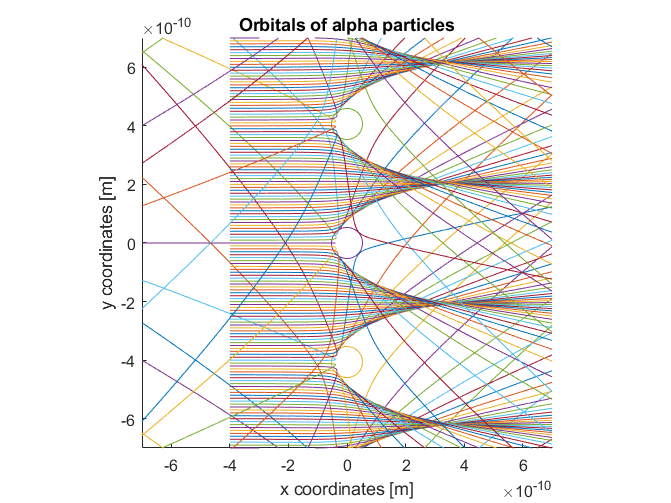

clear all, close all;

k=8.987551e+9; %Coulomb allando [Nm^2/C^2]
q1=2*1.6021766e-19; %alpha (helium) [C]
q2=79*1.6021766e-19; %arany [C]
m=6.624424e-27; %[kg]
km=k/m;
D=4.065e-10;

v0=5.2e+5; %kezdeti sebesseg [m/s]

dt=1e-18;
figure(3);
for k = -3:3
    rc=5.29177e-11;
    th=0:pi/60:2*pi;
    xunit=rc*cos(th);
    yunit=rc*sin(th)+k*D;
    hold on;
    plot(xunit, yunit)
end
hold on
    
for j=-150:150
    vx=v0;
    vy=0;
    rx=4e-10;
    ry=j*1e-11;
    x=-rx;
    y=ry;

    x_=[x];
    y_=[y];
    vx_=[vx];
    vy_=[vy];
    for i=0:10000
       
        r=sqrt(x^2+y^2);
        r1=sqrt(x^2+(y-D)^2);
        r2=sqrt(x^2+(y-2*D)^2);
        r3=sqrt(x^2+(y+D)^2);
        r4=sqrt(x^2+(y+2*D)^2);
        r5=sqrt(x^2+(y+3*D)^2);
        r6=sqrt(x^2+(y-3*D)^2);
        
        ax=km*q1*q2*x*(1/r^3+1/r1^3+1/r2^3+1/r3^3+1/r4^3+1/r5^3+1/r6^3);
        ay=km*q1*q2*(y/r^3+(y-D)/r1^3+(y-2*D)/r2^3+(y+D)/r3^3+(y+2*D)/r4^3+(y+3*D)/r5^3+(y-3*D)/r6^3);

        vx=vx+ax*dt;
        vy=vy+ay*dt;

        vx_=[vx_ vx];
        vy_=[vy_ vy];

        x=x+vx*dt;
        y=y+vy*dt;

        x_=[x_ x];
        y_=[y_ y];
        
    end
    plot(x_, y_)
    hold on;
end


pbaspect([1 1 1])
xlim([-7e-10, 7e-10]);
ylim([-7e-10, 7e-10]);
xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbitals of alpha particles');

Ezután a kísérletben részvevő részecskék kölcsönhatását leíró differenciál egyenlet alapján a Runge-Kutta 4th numerikus módszerrel számítottam ki az alpha részecskék pályáját (kódban látható a for ciklusban). A bezárt szögeket a részecskék kiindulópont, és a szimulációban a végpont koordinátáinak különbsége alapján határoztam meg: $$$\theta = atan2(y_{end}-y_0, x_{end}-x_0) \cdot \frac{180}{\pi}$$$.  A x tengely pozitív részével bezárt szöget számítottam: [0, 180] intervallumban (fokban), ezért a bezárt szögek abszolútértékét vettem. Készítettem oszlopdiagramot is a bezárt szögek gyakoriságát ábrázolva. A részecskék pályáját vizsgálva megállapítható, hogy nagyon közeli pontból vizsgálva a bezárt szögre más eredményt kaphatunk, hiszen nem minden esetben egyenes vonalú mozgást végeznek a részecskék a visszapattanás után.

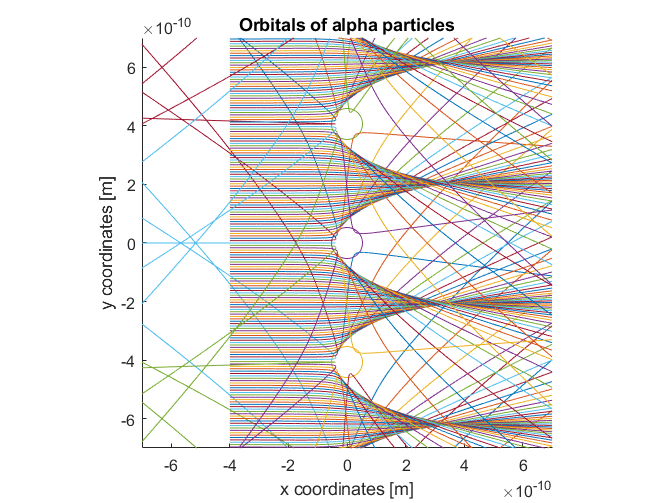

clear all, close all;

k=8.987551e+9; %Coulomb allando [Nm^2/C^2]
q1=2*1.6021766e-19; %alpha (helium) [C]
q2=79*1.6021766e-19; %arany [C]
m=6.624424e-27; %[kg]
km=k/m;
D=4.065e-10;
theta_=[];
y0=[];
th030=0;
th3060=0;
th6090=0;
th90120=0;
th120150=0;
th150180=0;


v0=5.2e+5; %kezdeti sebesseg [m/s]

dt=1e-18;
figure(4);
for k = -3:3
    rc=5.29177e-11;
    th=0:pi/60:2*pi;
    xunit=rc*cos(th);
    yunit=rc*sin(th)+k*D;
    hold on;
    plot(xunit, yunit)
end
hold on

for j=-180:180
    vx=v0;
    vy=0;
    rx=4e-10;
    ry=j*8.1e-12;
    x=-rx;
    y=ry;

    x_=[x];
    y_=[y];
    vx_=[vx];
    vy_=[vy];
    
    for i=0:10000
       
        r=sqrt(x^2+y^2);
        r1=sqrt(x^2+(y-D)^2);
        r2=sqrt(x^2+(y-2*D)^2);
        r3=sqrt(x^2+(y+D)^2);
        r4=sqrt(x^2+(y+2*D)^2);
        r5=sqrt(x^2+(y+3*D)^2);
        r6=sqrt(x^2+(y-3*D)^2);
        
        v_x(1)=dt*km*q1*q2*x*(1/r^3+1/r1^3+1/r2^3+1/r3^3+1/r4^3+1/r5^3+1/r6^3);
        v_y(1)=dt*km*q1*q2*(y/r^3+(y-D)/r1^3+(y-2*D)/r2^3+(y+D)/r3^3+(y+2*D)/r4^3+(y+3*D)/r5^3+(y-3*D)/r6^3);
        x_k(1)=dt*vx;
        y_k(1)=dt*vy;
        
        v_x(2)=dt*km*q1*q2*(x+x_k(1)/2)*(1/r^3+1/r1^3+1/r2^3+1/r3^3+1/r4^3+1/r5^3+1/r6^3);
        v_y(2)=dt*km*q1*q2*((y+y_k(1)/2)/r^3+((y+y_k(1)/2)-D)/r1^3+((y+y_k(1)/2)-2*D)/r2^3+((y+y_k(1)/2)+D)/r3^3+((y+y_k(1)/2)+2*D)/r4^3+((y+y_k(1)/2)+3*D)/r5^3+((y+y_k(1)/2)-3*D)/r6^3);
        x_k(2)=dt*(vx+v_x(1)/2);
        y_k(2)=dt*(vy+v_y(1)/2);
        
        v_x(3)=dt*km*q1*q2*(x+x_k(2)/2)*(1/r^3+1/r1^3+1/r2^3+1/r3^3+1/r4^3+1/r5^3+1/r6^3);
        v_y(3)=dt*km*q1*q2*((y+y_k(2)/2)/r^3+((y+y_k(2)/2)-D)/r1^3+((y+y_k(2)/2)-2*D)/r2^3+((y+y_k(2)/2)+D)/r3^3+((y+y_k(2)/2)+2*D)/r4^3+((y+y_k(2)/2)+3*D)/r5^3+((y+y_k(2)/2)-3*D)/r6^3);
        x_k(3)=dt*(vx+v_x(2)/2);
        y_k(3)=dt*(vy+v_y(2)/2);
        
        v_x(4)=dt*km*q1*q2*(x+x_k(3))*(1/r^3+1/r1^3+1/r2^3+1/r3^3+1/r4^3+1/r5^3+1/r6^3);
        v_y(4)=dt*km*q1*q2*((y+y_k(3))/r^3+((y+y_k(3))-D)/r1^3+((y+y_k(3))-2*D)/r2^3+((y+y_k(3))+D)/r3^3+((y+y_k(3))+2*D)/r4^3+((y+y_k(3))+3*D)/r5^3+((y+y_k(3))-3*D)/r6^3);
        x_k(4)=dt*(vx+v_x(3));
        y_k(4)=dt*(vy+v_y(3));
        
        vx=vx+(v_x(1)+2*v_x(2)+2*v_x(3)+v_x(4))/6;
        vy=vy+(v_y(1)+2*v_y(2)+2*v_y(3)+v_y(4))/6;
        
        vx_=[vx_ vx];
        vy_=[vy_ vy];
        
        x=x+(x_k(1)+2*x_k(2)+2*x_k(3)+x_k(4))/6;
        y=y+(y_k(1)+2*y_k(2)+2*y_k(3)+y_k(4))/6;
        
        x_=[x_ x];
        y_=[y_ y];

    end
    
    theta=atan2((y_(end)-y_(1)), (x_(end)-x_(1)))*180/pi;
    theta=abs(theta);
    
    if theta>=0 && theta<30
        th030=th030+1;
    end
    if theta>=30 && theta<60
        th3060=th3060+1;
    end
    if theta>=60 && theta<=90
        th6090=th6090+1;
    end
    if theta>90 && theta<=120
        th90120=th90120+1;
    end
    if theta>120 && theta<=150
        th120150=th120150+1;
    end
    if theta>150 && theta<=180
        th150180=th150180+1;
    end
    
    theta_=[theta_ theta];
    y0=[y0 ry];
    plot(x_, y_)
    hold on;
end
pbaspect([1 1 1])
xlim([-7e-10, 7e-10]);
ylim([-7e-10, 7e-10]);

xlabel('x coordinates [m]');
ylabel('y coordinates [m]');
title('Orbitals of alpha particles');

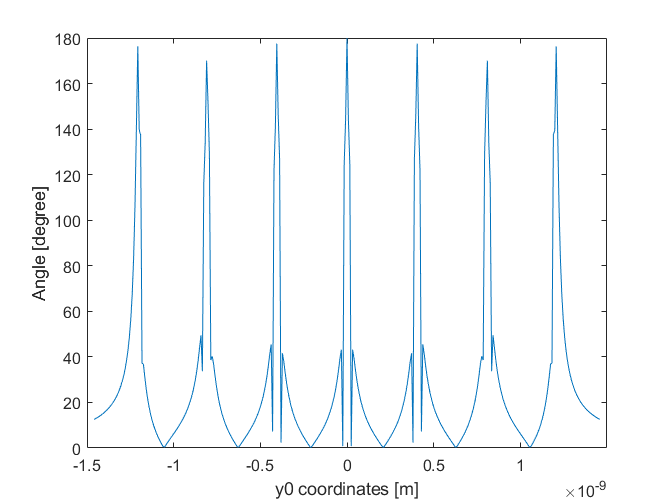


figure(5);
plot(y0, theta_)
xlim([-1.5e-9, 1.5e-9]);
ylim([0, 180]);
xlabel('y0 coordinates [m]');
ylabel('Angle [degree]');

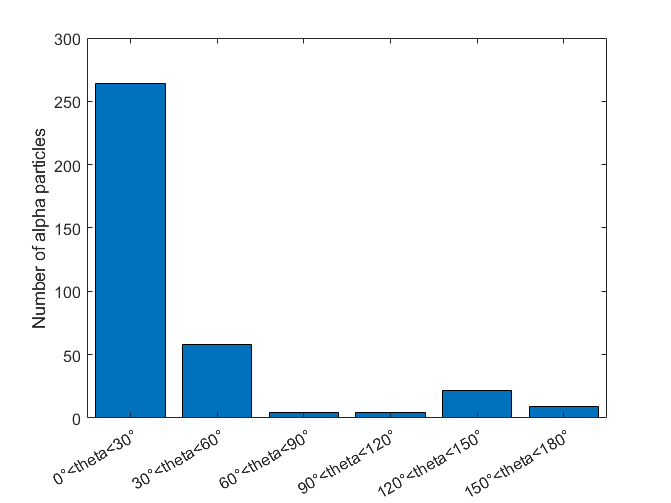


figure(6);
X = categorical({'0°<theta<30°','30°<theta<60°','60°<theta<90°','90°<theta<120°', '120°<theta<150°','150°<theta<180°'});
X = reordercats(X,{'0°<theta<30°','30°<theta<60°','60°<theta<90°','90°<theta<120°', '120°<theta<150°','150°<theta<180°'});
Y = [th030 th3060 th6090 th90120 th120150 th150180];
bar(X,Y);
ylabel('Number of alpha particles');

Készítette: Bánkövi Orsolya, DAZOJ8